# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 3.4.6 Polar Format Algorithm - Learjet

% Speed of light (m/s)
c = 299792458;

% Load the selected target
sig = LoadMonostaticSignatureFile('lear_0el_90az.sig');

% Set the polarization
signal = sig.vv;

% Get the frequency
frequency = sig.freq; 

% Set the image parameters
x_span = 30; % meters
y_span = 30; % meters
nx = 1024; % Number of bins in x-direction
ny = 1024; % Number of bins in y-direction

% Set the synthetic aperture azimuth span
az_start = 88; % degrees
az_end = 92; % degrees

% Set the image window type
window_type = 'None';

% Set the image dynamic range
dynamic_range = 35; % dB

% Choose the pulses in the azimuth range
sensor_az = [];
index = [];

% Loop over all azimuth angles
for i = 1:length(sig.az)
    if az_start <= sig.az(i) && sig.az(i) <= az_end
        sensor_az = [sensor_az, (sig.az(i))];
        index = [index, i];
    end
end

% Rotate for polar format
sensor_az = sensor_az - 90;
signal1 = signal(:, index, 65);
sensor_el = deg2rad(sig.el(65)) * ones(1, length(sensor_az));

% Get the data size
nf = length(frequency);
na = length(sensor_az);

% Calculate the signal in wavenumber space
kx = zeros(nf, na);
ky = zeros(nf, na);
kc = 2 * pi * frequency / c;

ca = cosd(sensor_az);
sa = sind(sensor_az);

for i = 1:na
    kx(:, i) = kc .* ca(i);
    ky(:, i) = kc .* sa(i);
end


#### Plot the signal in wavenumber space

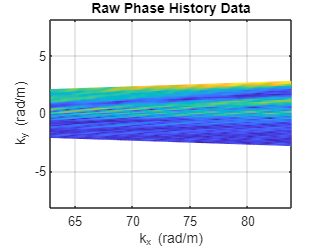

figure; pcolor(kx, ky, abs(signal1)); shading flat
title('Raw Phase History Data')
xlabel('k_x (rad/m)')
ylabel('k_y (rad/m)')
grid on
axis equal

% Set up the wavenumber space regular grid
kxmin = min(min(kx));
kxmax = max(max(kx));

kymin = min(min(ky));
kymax = max(max(ky));

kxp = linspace(kxmin, kxmax, 400);
kyp = linspace(kymin, kymax, 400);

[kxp, kyp] = meshgrid(kxp, kyp);

% Set up the interpolation
F = scatteredInterpolant(kx(:), ky(:), signal1(:), 'linear', 'nearest');

% Perform interpolation
new_signal = F(kxp, kyp);


#### Plot the reformatted phase history data

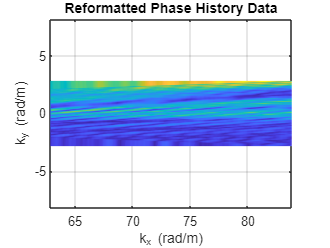

figure; pcolor(kxp, kyp, abs(new_signal)); shading flat
title('Reformatted Phase History Data')
xlabel('k_x (rad/m)')
ylabel('k_y (rad/m)') 
grid on
axis equal

% Get the frequency step size
frequency_step = c / (2 * pi) * (kxp(1,2) - kxp(1,1));

% Calculate the maximum scene size and resolution
range_extent = c / (2 * frequency_step);

% Calculate the range window for the pulses
range_window = linspace(-0.5 * range_extent, 0.5 * range_extent, nx);

% Get the frequency step size
frequency_step = c / (2 * pi) * (kyp(2,1) - kyp(1,1));

% Calculate the maximum scene size and resolution
cross_range_extent = c / (2 * frequency_step);

% Calculate the range window for the pulses
cross_range_window = linspace(-0.5 * cross_range_extent, 0.5 * cross_range_extent, ny);

% Calculate the range compressed signal
r_signal = fftshift(ifft(new_signal, nx, 2), 2);

% Calculate the formatted ky wavenuber
kypp = linspace(min(min(ky)), max(max(ky)), 400);

% Calculate the focused image
ra_signal = fftshift(ifft(r_signal, ny, 1), 1);

#### Plot the range compressed data

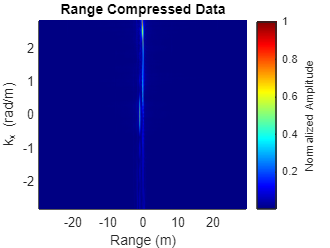

figure; pcolor(range_window, kypp, abs(r_signal)/max(max(abs(r_signal)))); shading flat
title('Range Compressed Data')
xlabel('Range (m)')
ylabel('k_x (rad/m)')
h = colorbar;
ylabel(h, 'Normalized Amplitude');
colormap jet

#### Plot the focused image

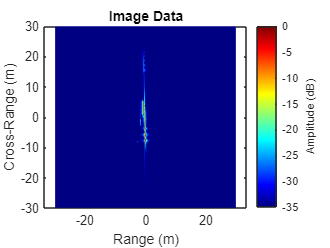

pcolor(range_window, cross_range_window, 20*log10(abs(ra_signal)/max(max(abs(ra_signal))))); shading flat
caxis([-abs(dynamic_range), 0])
title('Image Data')
xlabel('Range (m)')
ylabel('Cross-Range (m)')
xlim([-x_span, x_span])
ylim([-y_span, y_span])
h = colorbar;
ylabel(h, 'Amplitude (dB)')
axis equal
colormap jet